# ME-8930 | LMIs for Robust & Optimal Control Design

## Capstone Project

**Team:** Chinmay Samak and Tanmay Samak

clear;
close;
clc;

## System Modeling & Analysis

% Environment parameters

u_fl = 0.8; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.8; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.8; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.8; % Coefficient of friction for ground and RR tire interconnect

% Vehicle parameters

m = 1630; % Mass [kg]
J = 3853; % Yaw moment of inertia [kg-m^2]
l_f = 1.2313; % Distance from CG to front axel [m]
l_r = 1.4087; % Distance from CG to rear axel [m]
l = l_f + l_r; % Wheelbase [m]
C_fl = 50000; % Cornering stiffness of FL tire [N/rad]
C_fr = 50000; % Cornering stiffness of FR tire [N/rad]
C_rl = 50000; % Cornering stiffness of RL tire [N/rad]
C_rr = 50000; % Cornering stiffness of RR tire [N/rad]

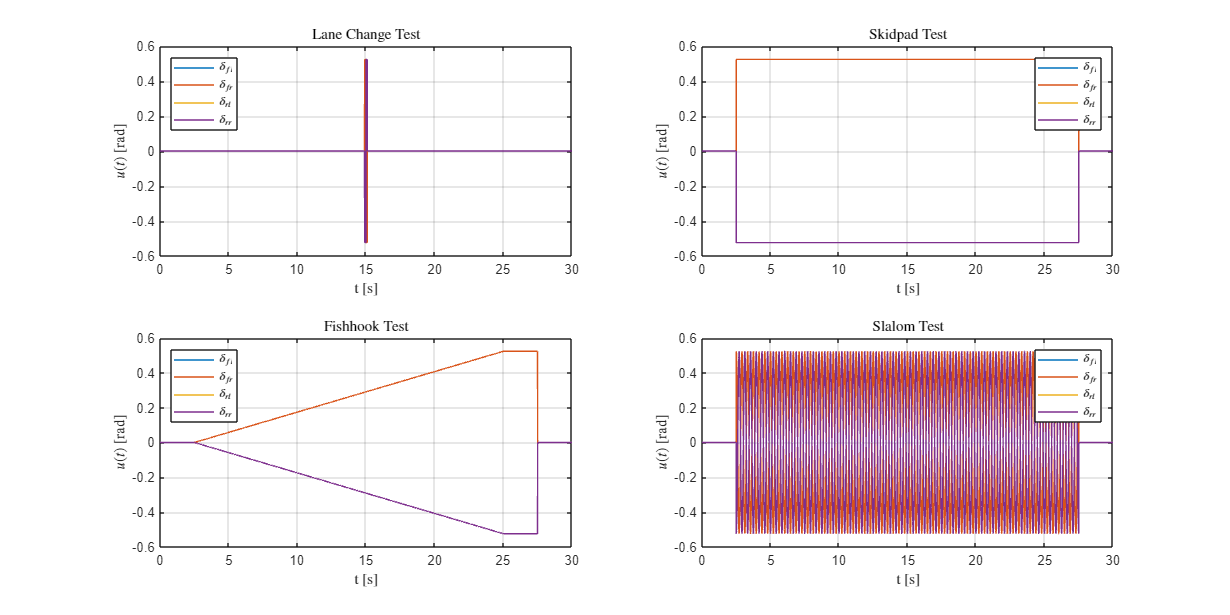

% Maneuver parameters

v = 20; % Vehicle velocity [m/s]

% Straight-line test (zero input)
u1_straight_line = zeros(1,30000);
u2_straight_line = zeros(1,30000);
u3_straight_line = zeros(1,30000);
u4_straight_line = zeros(1,30000);
u_straight_line = [u1_straight_line; u2_straight_line; u3_straight_line; u4_straight_line];
w_straight_line = ones(1,30000);

% Lane change test (impulse input)
u1_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(30)) ones(1,100)*(deg2rad(-30)) ones(1,14900)*(deg2rad(0))];
u2_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(30)) ones(1,100)*(deg2rad(-30)) ones(1,14900)*(deg2rad(0))];
u3_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(-30)) ones(1,100)*(deg2rad(30)) ones(1,14900)*(deg2rad(0))];
u4_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(-30)) ones(1,100)*(deg2rad(30)) ones(1,14900)*(deg2rad(0))];
u_lane_change = [u1_lane_change; u2_lane_change; u3_lane_change; u4_lane_change];
w_lane_change = zeros(1,30000);

% Skidpad test (step input)
u1_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u2_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u3_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u4_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u_skidpad = [u1_skidpad; u2_skidpad; u3_skidpad; u4_skidpad];
w_skidpad = zeros(1,30000);

% Fishhook test (ramp input)
angles = deg2rad(linspace(0,30,22500));
u1_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u2_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u3_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u4_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u_fishhook = [u1_fishhook; u2_fishhook; u3_fishhook; u4_fishhook];
w_fishhook = zeros(1,30000);

% Slalom test (sine input)
n_cones = 60;
angles = linspace(0,2*n_cones*pi,25000);
u1_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u2_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u3_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u4_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u_slalom = [u1_slalom; u2_slalom; u3_slalom; u4_slalom];
w_slalom = zeros(1,30000);

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [4000, 2000];
% Lane change (impulse)
subplot(2,2,1)
plot(t/1000,u1_lane_change)
hold on;
plot(t/1000,u2_lane_change)
plot(t/1000,u3_lane_change)
plot(t/1000,u4_lane_change)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Lane Change Test','Interpreter','latex')
grid on;
hold off;
% Skidpad (step)
subplot(2,2,2)
plot(t/1000,u1_skidpad)
hold on;
plot(t/1000,u2_skidpad)
plot(t/1000,u3_skidpad)
plot(t/1000,u4_skidpad)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Skidpad Test','Interpreter','latex')
grid on;
hold off;
% Fishhook (ramp)
subplot(2,2,3)
plot(t/1000,u1_fishhook)
hold on;
plot(t/1000,u2_fishhook)
plot(t/1000,u3_fishhook)
plot(t/1000,u4_fishhook)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Fishhook Test','Interpreter','latex')
grid on;
hold off;
% Slalom (sine)
subplot(2,2,4)
plot(t/1000,u1_slalom)
hold on;
plot(t/1000,u2_slalom)
plot(t/1000,u3_slalom)
plot(t/1000,u4_slalom)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Slalom Test','Interpreter','latex')
grid on;
hold off;

% Vehicle model

a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));

b11 = (u_fl*C_fl)/(m*v);
b12 = (u_fr*C_fr)/(m*v);
b13 = (u_rl*C_rl)/(m*v);
b14 = (u_rr*C_rr)/(m*v);
b21 = (l_f*u_fl*C_fl)/J;
b22 = (l_f*u_fr*C_fr)/J;
b23 = -(l_r*u_rl*C_rl)/J;
b24 = -(l_r*u_rr*C_rr)/J;

A = [a11 a12;
     a21 a22];

B = [b11 b12 b13 b14;
     b21 b22 b23 b24];

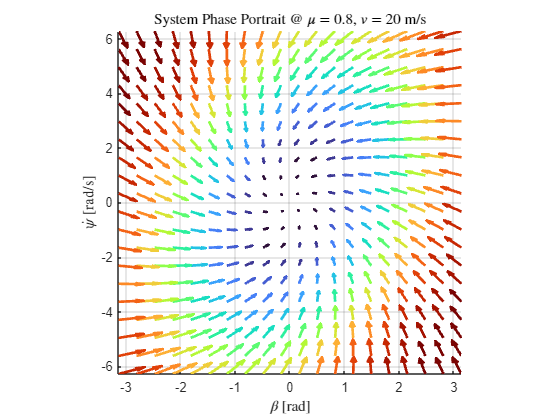

% System phase portrait

u_fl = 0.8; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.8; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.8; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.8; % Coefficient of friction for ground and RR tire interconnect
v = 20; % Vehicle velocity [m/s]

% Compute system matrix
a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
A = [a11 a12;
     a21 a22];

% Define a range of initial conditions
X1_range = linspace(-3.14159, 3.14159, 20);
X2_range = linspace(-6.28319, 6.28319, 20);

% Create a meshgrid of initial conditions
[X1, X2] = meshgrid(X1_range, X2_range);

% Initialize vectors to store the derivatives
X1_dot = zeros(size(X1));
X2_dot = zeros(size(X2));

% Calculate the derivatives for each initial condition
for i = 1:numel(X1)
    X_dot = A * [X1(i); X2(i)];
    X1_dot(i) = X_dot(1);
    X2_dot(i) = X_dot(2);
end
Z = (sqrt(X1_dot.^2 + X2_dot.^2));
Z = Z/max(Z,[],'all');
Z = reshape(Z.',1,[]);
[sortedZ, sortedIdx] = sort(Z);
sortedIdx = reshape(sortedIdx,[20,20]).';
X1_s = X1(sortedIdx);
X2_s = X2(sortedIdx);
X1_dot_s = X1_dot(sortedIdx);
X2_dot_s = X2_dot(sortedIdx);

% Plot
fig = figure(); 
fig.Position(3:4) = [560, 420];
cmap = turbo(size(X1_s,1)); 
hold on;
for i = 1:size(X1_s,1)
    quiver(X1_s(i,:),X2_s(i,:),X1_dot_s(i,:),X2_dot_s(i,:), .2, 'Color', cmap(i,:), 'LineWidth',2)
end
hold off;
xlabel('X1');
ylabel('X2');
xlabel('$\beta$ [rad]','Interpreter','latex');
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex');
title('System Phase Portrait @ $\mu = 0.8$, $v = 20$ m/s','Interpreter','latex');
grid on;
axis tight;
pbaspect([1 1 1])

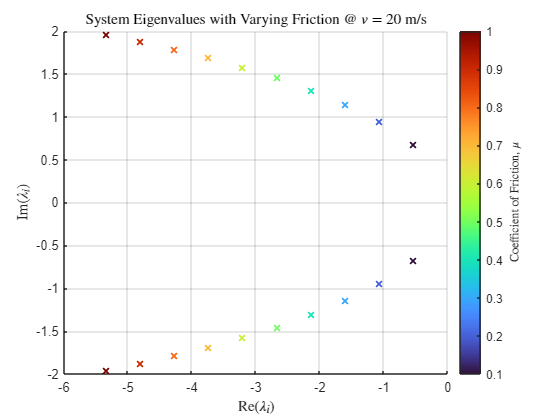

% System eignvalues with varying friction

EV = []; % Array to store system eigenvalues
v = 20; % Vehicle velocity [m/s]
for u=0.1:0.1:1
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
u=0.1:0.1:1;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],u,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],u,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Coefficient of Friction, $\mu$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Friction @ $v = 20$ m/s','Interpreter','latex');
grid on;

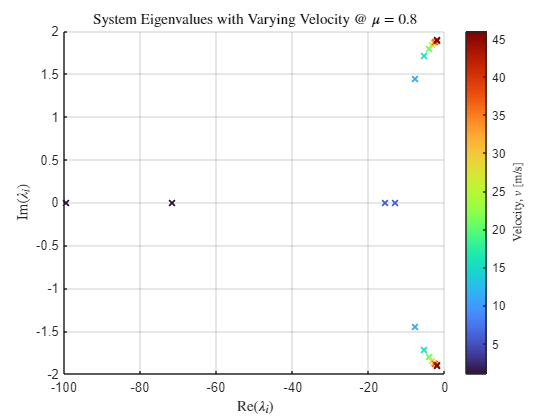

% System eignvalues with varying velocity

EV = []; % Array to store system eigenvalues
u = 0.8; % Coefficient of friction for ground and tire interconnect
for v=1:5:50
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
v=1:5:50;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],v,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],v,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Velocity, $v$ [m/s]','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Velocity @ $\mu = 0.8$','Interpreter','latex');
grid on;

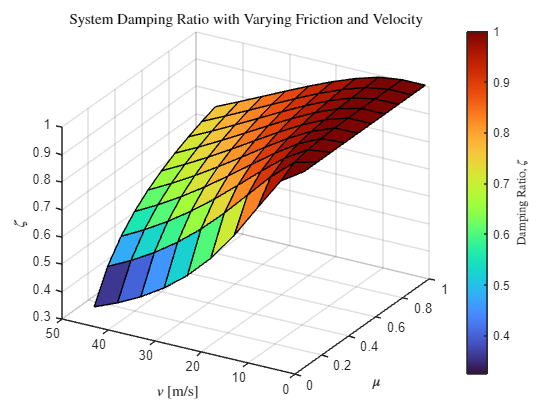

% System damping ratio with varying friction and velocity

zeta = []; % Array to store system eigenvalues
for u=0.1:0.1:1
    for v=1:5:50
        % Set friction value
        u_fl = u;
        u_fr = u;
        u_rl = u;
        u_rr = u;
        % Update system matrix
        a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
        a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
        a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
        a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
        A = [a11 a12;
             a21 a22];
        % Compute damping ratio
        EV = eig(A);
        zeta(:,end+1) = -real(EV)./abs(EV);
    end
end

% Plot
u=0.1:0.1:1;
v=1:5:50;
[X,Y] = meshgrid(u,v);
Z = reshape(zeta(1, :), 10, 10);
fig = figure(); 
fig.Position(3:4) = [560, 420];
s = surf(X,Y,Z,'FaceAlpha',1.0);
hold on;
cb = colorbar();
ylabel(cb,'Damping Ratio, $\zeta$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('$\mu$','Interpreter','latex');
ylabel('$v$ [m/s]','Interpreter','latex');
zlabel('$\zeta$','Interpreter','latex');
title('System Damping Ratio with Varying Friction and Velocity','Interpreter','latex');
grid on;
view([-60 30]);

## Open Loop System Simulation

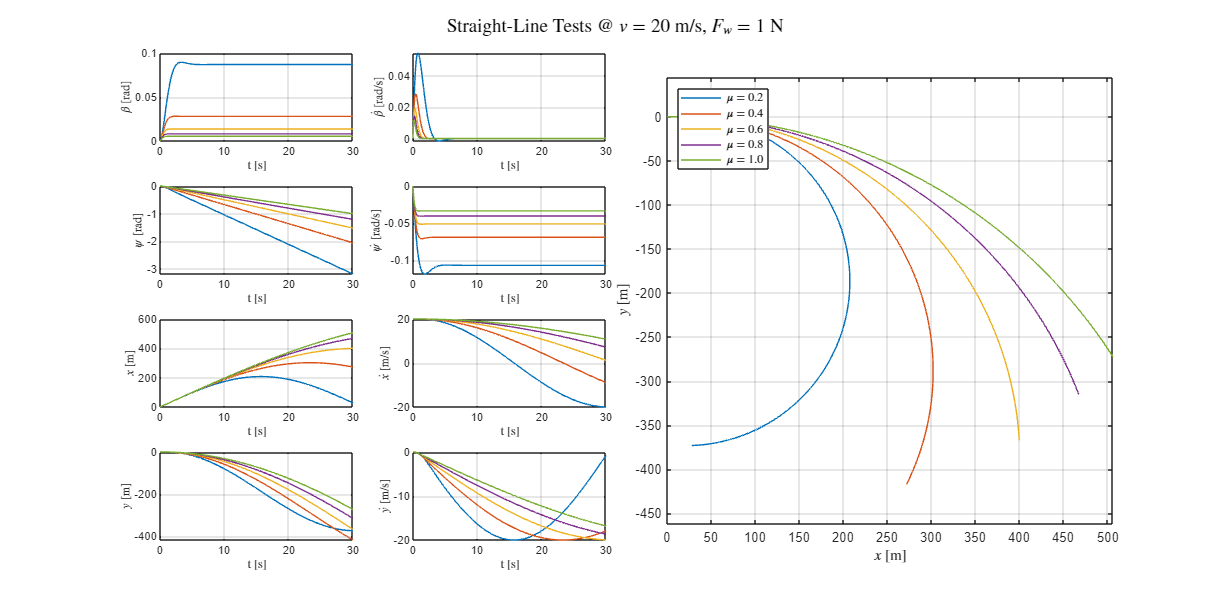

% Simulate straight-line motion with varying friction and disturbance

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 20; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f^2-l_r^2)/l];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_straight_line(:,t) + B_d*w_straight_line(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Straight-Line Tests @ $v = 20$ m/s, $F_w = 1$ N','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

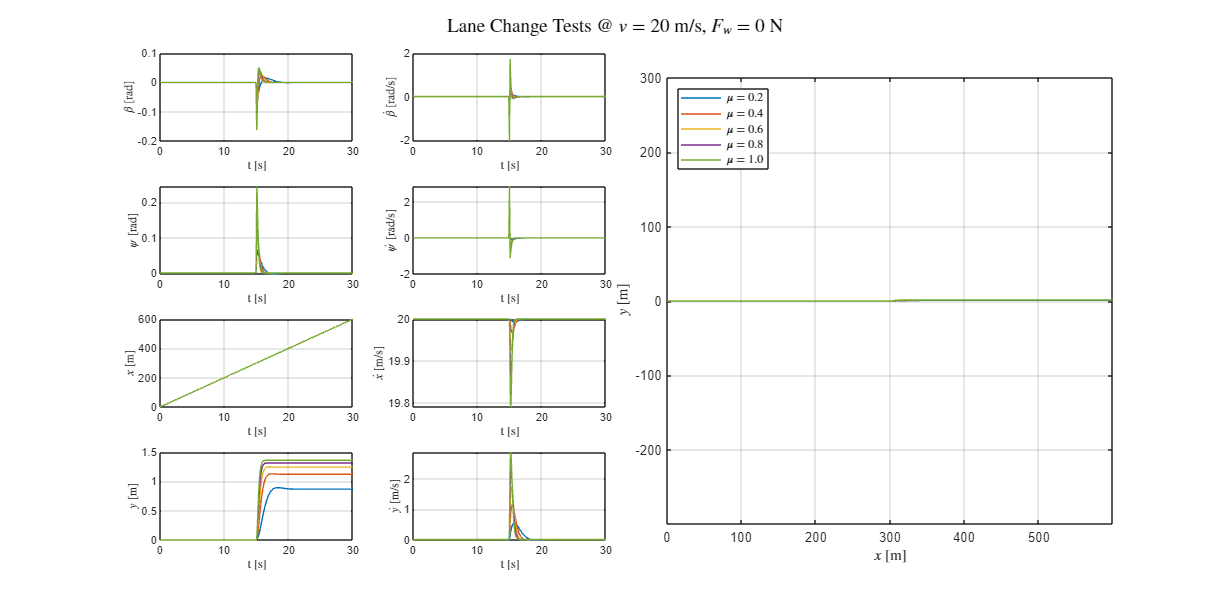

% Simulate lane change tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 20; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f^2-l_r^2)/l];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_lane_change(:,t) + B_d*w_lane_change(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Lane Change Tests @ $v = 20$ m/s, $F_w = 0$ N','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

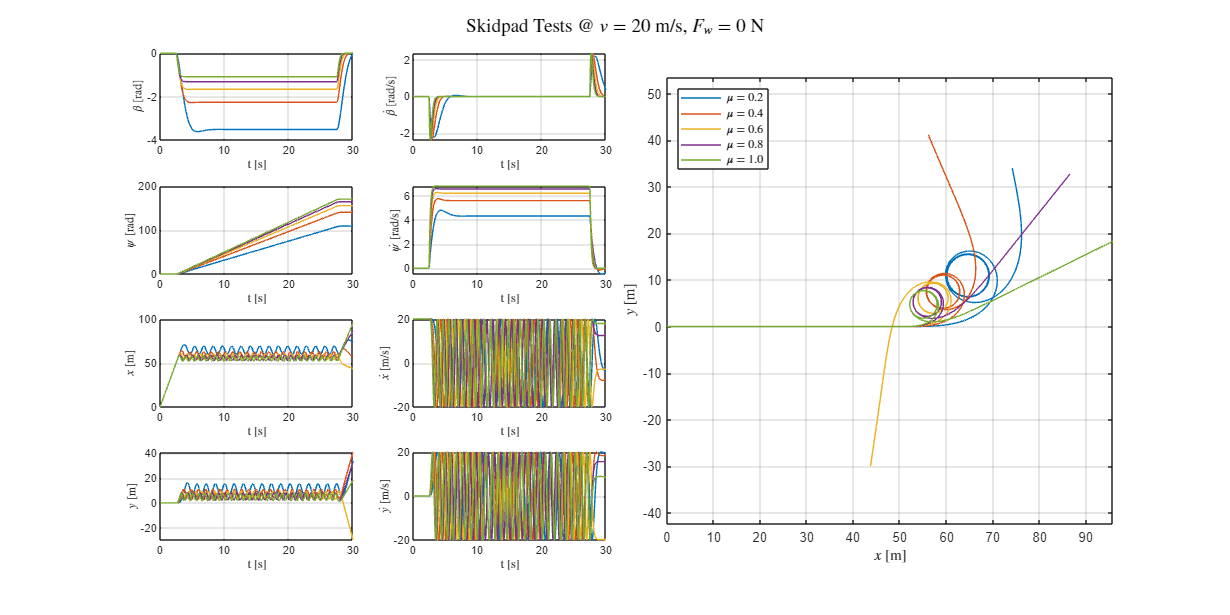

% Simulate skidpad tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 20; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f^2-l_r^2)/l];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_skidpad(:,t) + B_d*w_skidpad(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Skidpad Tests @ $v = 20$ m/s, $F_w = 0$ N','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

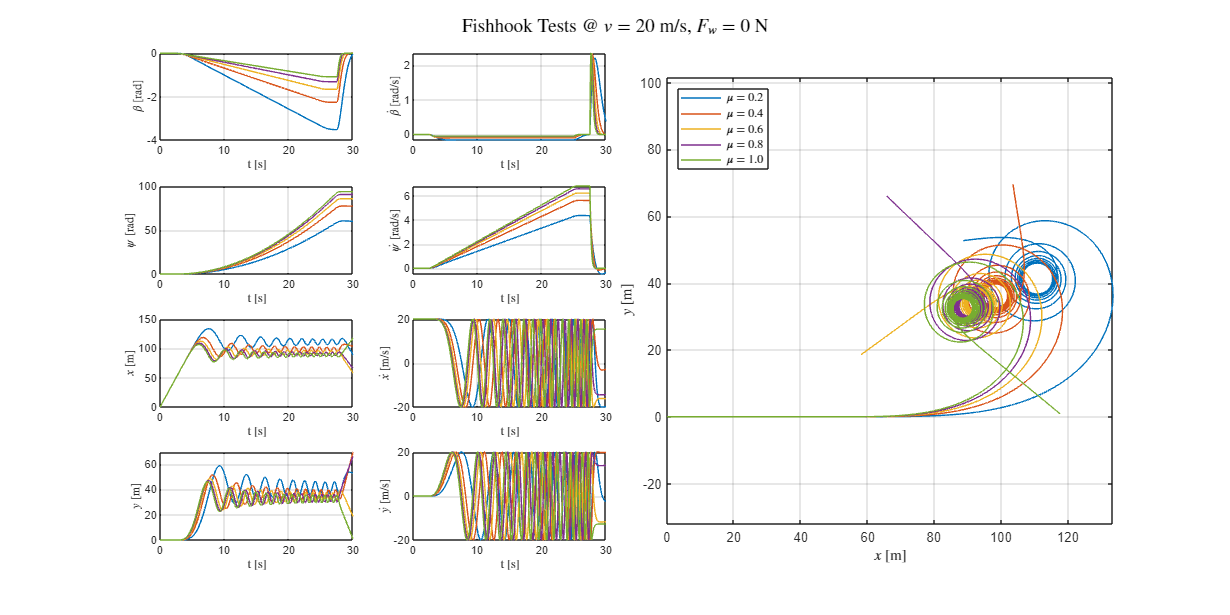

% Simulate fishhook tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 20; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f^2-l_r^2)/l];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_fishhook(:,t) + B_d*w_fishhook(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Fishhook Tests @ $v = 20$ m/s, $F_w = 0$ N','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

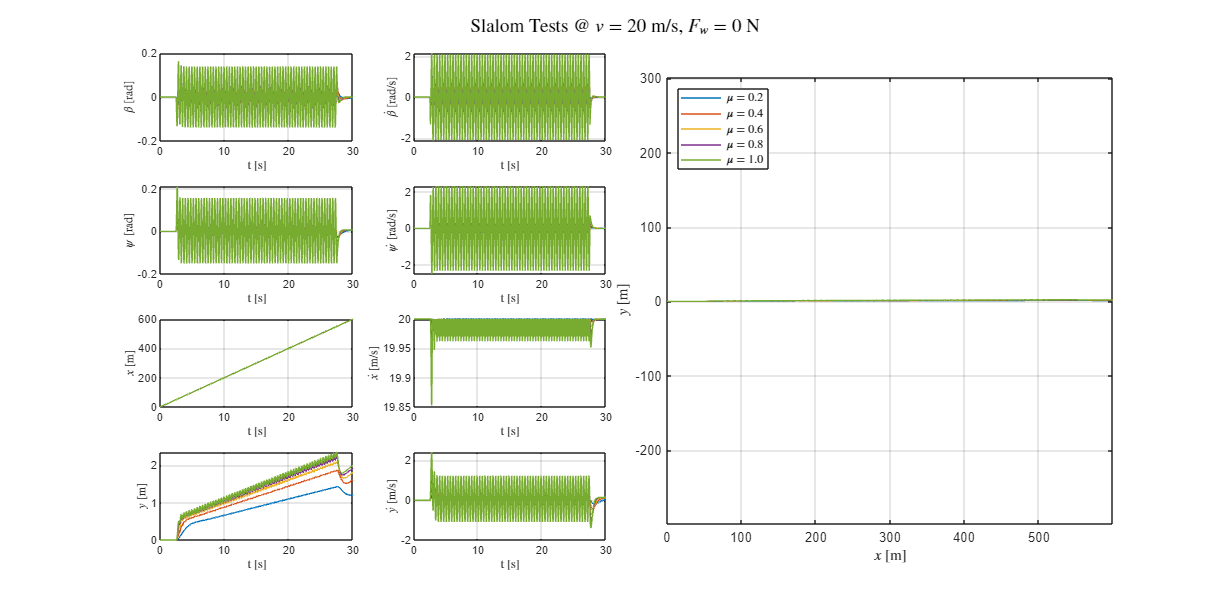

% Simulate slalom tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 20; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f^2-l_r^2)/l];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_slalom(:,t) + B_d*w_slalom(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Slalom Tests @ $v = 20$ m/s, $F_w = 0$ N','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

## Controller Design

% Operating conditions
v = 20; % Vehicle velocity [m/s]

% Vehicle model with affine dependence on u_fl, u_fr, u_rl and u_rr

Ap0 = [0 -1;
       0  0]; % Nominal system matrix

Ap1 = [-C_fl/(m*v)    -(l_f*C_fl)/(m*v^2);
      -(l_f*C_fl)/J  -(l_f^2*C_fl)/(J*v)]; % Affine dependence on u_fl

Ap2 = [-C_fr/(m*v)    -(l_f*C_fr)/(m*v^2);
      -(l_f*C_fr)/J  -(l_f^2*C_fr)/(J*v)]; % Affine dependence on u_fr

Ap3 = [-C_rl/(m*v)     (l_r*C_rl)/(m*v^2);
      (l_r*C_rl)/J   -(l_r^2*C_rl)/(J*v)]; % Affine dependence on u_rl

Ap4 = [-C_rr/(m*v)     (l_r*C_rr)/(m*v^2);
      (l_r*C_rr)/J   -(l_r^2*C_rr)/(J*v)]; % Affine dependence on u_rr

% Ap = Ap0 + u_fl.*Ap1 + u_fr.*Ap2 + u_rl.*Ap3 + u_rr.*Ap4

Bp0 = [0 0 0 0;
       0 0 0 0]; % Nominal input matrix

Bp1 = [C_fl/(m*v)   0 0 0;
      (l_f*C_fl)/J 0 0 0]; % Affine dependence on u_fl

Bp2 = [0 C_fr/(m*v)   0 0;
       0 (l_f*C_fr)/J 0 0]; % Affine dependence on u_fr

Bp3 = [0 0 C_rl/(m*v)    0;
       0 0 -(l_r*C_rl)/J 0]; % Affine dependence on u_rl

Bp4 = [0 0 0 C_rr/(m*v);
       0 0 0 -(l_r*C_rr)/J]; % Affine dependence on u_rr

% Bp = Bp0 + u_fl.*Bp1 + u_fr.*Bp2 + u_rl.*Bp3 + u_rr.*Bp4

Dp = [1/(m*v); (l_f^2-l_r^2)/l];

Cp1 = [1 0;
       0 1;
       0 0;
       0 0;
       0 0;
       0 0];

By1 = [0 0 0 0;
       0 0 0 0;
       1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];

Dy = [0;
      0;
      0;
      0;
      0;
      0];

Cp2 = [1 0;
       0 1;
       0 0;
       0 0;
       0 0;
       0 0];

By2 = [0 0 0 0;
       0 0 0 0;
       1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];

O = [0;
     0;
     0;
     0;
     0;
     0];

[u_fl_lim, u_fr_lim, u_rl_lim, u_rr_lim] = deal([0.1 1], [0.1 1], [0.1 1], [0.1 1]);

pv = pvec('box', [u_fl_lim; u_fr_lim; u_rl_lim; u_rr_lim]); % Range of parameter variation
pvinfo(pv); % Print uncertain parameter(s) information

Vector of 4 parameters ranging in a box




S_ol = psys(pv,[ltisys(Ap0, [Dp Bp0], [Cp1; Cp2], [Dy By1; O By2], 1), ...
                ltisys(Ap1, [zeros(2,1) Bp1], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                ltisys(Ap2, [zeros(2,1) Bp2], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                ltisys(Ap3, [zeros(2,1) Bp3], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                ltisys(Ap4, [zeros(2,1) Bp4], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0)]);

psinfo(S_ol); % Print open-loop system information

Affine parameter-dependent model with 4 parameters (5 systems) 
    Each system has 2 state(s), 5 input(s), and 12 output(s)



% Test robust stability of open-loop system via parametric Lyapunov functions
[tmin, Q0, Q1, Q2, Q3] = pdlstab(S_ol, [0 0])


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.124843
     2                        0.020427
     3                        0.020427
     4                    8.819273e-03
     5                    8.122708e-03
     6                    6.007728e-03
     7                    5.293805e-03
     8                    5.293805e-03
***                 new lower bound: -1.021966e-04
     9                    5.293805e-03
***                 new lower bound: 3.348398e-04

 Result:  best value of t: 5.293805e-03
          f-radius saturation:  0.000% of R =  1.00e+07

 These LMI constraints were found infeasible 

 Trying for the transposed system... 

 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negativ

tmin = 0.0061

Q0 =     0.0202    0.0030
    0.0030    0.0050


Q1 =    -0.0480    0.0042
    0.0042   -0.0007


Q2 =    -0.0480    0.0042
    0.0042   -0.0007


Q3 =     0.1282    0.0113
    0.0113    0.0016


% region = lmireg; % Pole placement constraint (intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4)
region = [0.2000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9239 + 0.0000i  -0.3827 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3827 + 0.0000i   0.9239 + 0.0000i];

g1_opt_global = msfsyn(S_ol, size(By2), [0 0 1 0], region) % Optimal quadratic H∞ performance subject to the pole placement constraint


 Optimization of the H-infinity performance G :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5                  87.009823
     6                   8.058343
     7                   8.058343
     8                   3.933040
     9                   3.933040
    10                   1.399072
    11                   1.399072
    12                   1.399072
    13                   0.442640
    14                   0.389004
    15                   0.389004
    16                   0.179271
    17                   0.179271
    18                   0.179271
    19                   0.107728
    20                   0.107728
    21                   0.107728
    22                   0.107728
    23                   0.085550
    24                   0.085550
    25                   0.076235
    26                   0.076235
***       

g1_opt_global = 0.0516

g1_opt = []; % Array to store γ1* (Γee)
g2_opt = []; % Array to store γ2* (Γep)
K = []; % Array to store state-feedback controller gain K
S_cl = []; % Array to store closed-loop system representations
X = []; % Array to store corresponding Lyapunov matrices

for g = g1_opt_global:0.01:0.25 % Bound on H∞ performance
    [g1_opt(end+1), g2_opt(end+1), K(:,:,end+1), S_cl(:,:,end+1), X(:,:,end+1)] = msfsyn(S_ol, size(By2), [g 0 0 1], region); % For a prescribed H∞ performance g>0, compute the best H2 performance g2opt
end


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31                   0.361272
    32                   0.136952
    33                   0.136952
    34                   0.136952
    35                   0.105648
    36                   0.093124
***                 new lower bound:    -1.023416
    37                   0.084160
***                 new lower bound:    -0.440186
    38                   0.084160
***                 new lower bound:    -0.257575
    39                   0.078364
***                 new lower bound:    -0.246913
    40                   0.072451
***                 new lower bound:

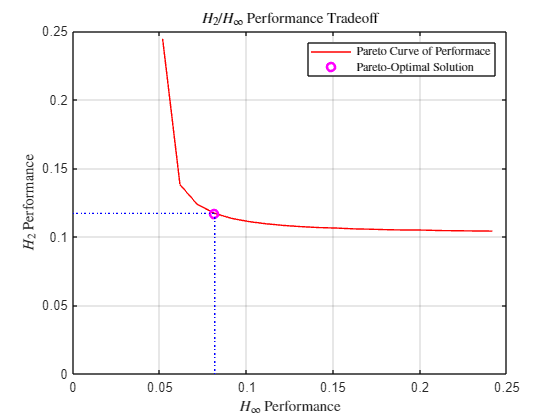

% Find Pareto-optimal solution
dist = sqrt(g1_opt.^2 + g2_opt.^2);
idx_popt = find(dist == min(dist));
g1_popt = g1_opt(idx_popt); % γ1* (Γee)
g2_popt = g2_opt(idx_popt); % γ2* (Γep)
K = K(:,:,idx_popt); % State-feedback controller gain K
S_cl = S_cl(:,:,idx_popt); % Closed-loop system representation
X = X(:,:,idx_popt); % Lyapunov matrix

% Plot
figure()
plot(g1_opt, g2_opt, 'r-')
hold on
plot(g1_popt, g2_popt, 'mo', LineWidth=2)
plot([0, g1_popt], [g2_popt, g2_popt], 'b:');
plot([g1_popt, g1_popt], [0, g2_popt], 'b:');
xlabel('$H_{\infty}$ Performance', 'Interpreter','latex')
ylabel('$H_2$ Performance', 'Interpreter','latex')
legend('Pareto Curve of Performace', 'Pareto-Optimal Solution', 'Interpreter','latex')
hold off
title('$H_2/H_{\infty}$ Performance Tradeoff','Interpreter','latex');
grid('on')

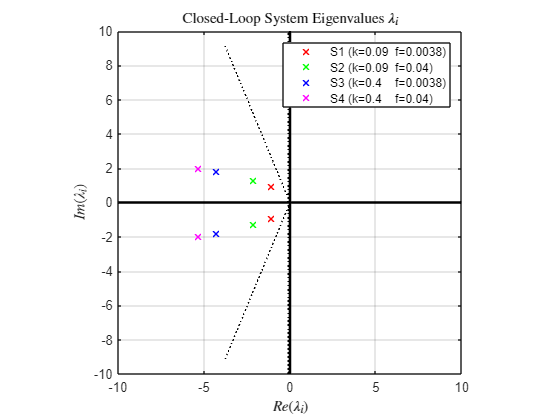

Pcl_kmin_fmin = psinfo(S_ol, 'eval', [0.2 0.2 0.2 0.2]); % k=0.09 f=0.0038
Pcl_kmin_fmax = psinfo(S_ol, 'eval', [0.4 0.4 0.4 0.4]); % k=0.09 f=0.04
Pcl_kmax_fmin = psinfo(S_ol, 'eval', [0.8 0.8 0.8 0.8]); % k=0.4  f=0.0038
Pcl_kmax_fmax = psinfo(S_ol, 'eval', [1.0 1.0 1.0 1.0]); % k=0.4  f=0.04

[A_kmin_fmin, B_kmin_fmin, C_kmin_fmin, D_kmin_fmin] = ltiss(Pcl_kmin_fmin);
[A_kmin_fmax, B_kmin_fmax, C_kmin_fmax, D_kmin_fmax] = ltiss(Pcl_kmin_fmax);
[A_kmax_fmin, B_kmax_fmin, C_kmax_fmin, D_kmax_fmin] = ltiss(Pcl_kmax_fmin);
[A_kmax_fmax, B_kmax_fmax, C_kmax_fmax, D_kmax_fmax] = ltiss(Pcl_kmax_fmax);

Pcl_kmin_fmin_ss = ss(A_kmin_fmin, B_kmin_fmin, C_kmin_fmin, D_kmin_fmin);
Pcl_kmin_fmax_ss = ss(A_kmin_fmax, B_kmin_fmax, C_kmin_fmax, D_kmin_fmax);
Pcl_kmax_fmin_ss = ss(A_kmax_fmin, B_kmax_fmin, C_kmax_fmin, D_kmax_fmin);
Pcl_kmax_fmax_ss = ss(A_kmax_fmax, B_kmax_fmax, C_kmax_fmax, D_kmax_fmax);

t = 0:0.01:30;

y_kmin_fmin = step(Pcl_kmin_fmin_ss, t);
y_kmin_fmax = step(Pcl_kmin_fmax_ss, t);
y_kmax_fmin = step(Pcl_kmax_fmin_ss, t);
y_kmax_fmax = step(Pcl_kmax_fmax_ss, t);

figure()
% Plot horizontal line passing through 0
plot([-10, 10], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot vertical line passing through 0
plot([0, 0], [-10, 10], 'k-', 'LineWidth', 2);
% Plot vertical line passing through -0.1
plot([-0.1, -0.1], [-10, 10], 'k:', 'LineWidth', 1);
% Plot two lines intersecting at 0 and manking an angle of (3*pi)/4 radians
angle = pi/2 + (pi - (3*pi)/4)/2; length = 10; x0 = 0; y0 = 0;
plot([x0, x0 + length * cos(angle)], [y0, y0 + length * sin(angle)], 'k:', 'LineWidth', 1);
plot([x0, x0 + length * cos(-angle)], [y0, y0 + length * sin(-angle)], 'k:', 'LineWidth', 1);
% Plot system eigenvalues
plot(real(eig(A_kmin_fmin)), imag(eig(A_kmin_fmin)), 'rx', LineWidth=1), grid
plot(real(eig(A_kmin_fmax)), imag(eig(A_kmin_fmax)), 'gx', LineWidth=1), grid
plot(real(eig(A_kmax_fmin)), imag(eig(A_kmax_fmin)), 'bx', LineWidth=1), grid
plot(real(eig(A_kmax_fmax)), imag(eig(A_kmax_fmax)), 'mx', LineWidth=1), grid
xlabel('$Re(\lambda_i)$','Interpreter','latex')
ylabel('$Im(\lambda_i)$','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Eigenvalues $\lambda_i$','Interpreter','latex')
legend('', '', '', '', '', 'S1 (k=0.09  f=0.0038)','S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')

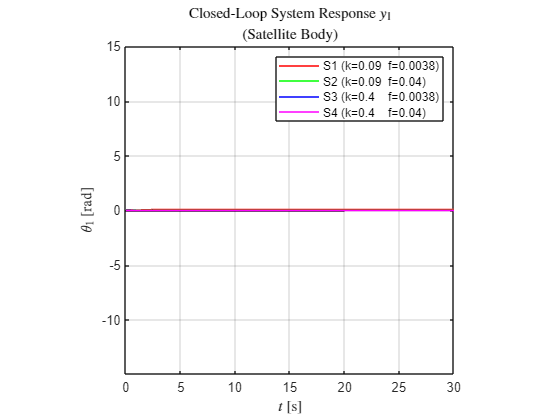

figure()
% Plot horizontal line passing through 0
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot system response
plot(t, y_kmin_fmin(:, 1, 1), 'r-'), grid
plot(t, y_kmin_fmax(:, 1, 1), 'g-'), grid
plot(t, y_kmax_fmin(:, 1, 1), 'b-'), grid
plot(t, y_kmax_fmax(:, 1, 1), 'm-'), grid
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$\theta_1$ [rad]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Response $y_1$', '(Satellite Body)','Interpreter','latex')
legend('', 'S1 (k=0.09  f=0.0038)','S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')

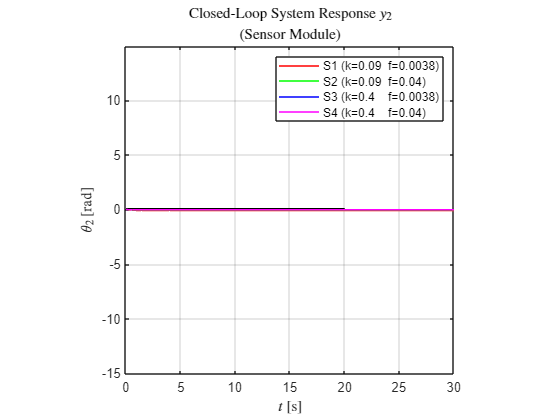

figure()
% Plot horizontal line passing through 0
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot system response
plot(t, y_kmin_fmin(:, 2, 1), 'r-'), grid
plot(t, y_kmin_fmax(:, 2, 1), 'g-'), grid
plot(t, y_kmax_fmin(:, 2, 1), 'b-'), grid
plot(t, y_kmax_fmax(:, 2, 1), 'm-'), grid
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$\theta_2$ [rad]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Response $y_2$', '(Sensor Module)','Interpreter','latex')
legend('', 'S1 (k=0.09  f=0.0038)','S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')